# Dummy-coded Motor maps (expect rating & outcome rating)

Model (CESeO)

- parameter:

-    0 **C**ue onset, 

-    1 **E**xpectationRating onset 

-    0 **S**timulus onset

-    0        pmod: **e**xpectation rating (angle)

-    1 **O**utcomeRating onset

- Motion covariate: 24DOF + CSF

- Spike combined into one regressor (Incorrect)

#### Motor :: load dataset

clear all; close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0012.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel/sub-0014/con_0012.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 30749796 bytes
Loading image number:    77
Elapsed time is 3.304894 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7372512  Bit rate: 22.81 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXexpect_P', 'stimXexpect_V', 'stimXexpect_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXexpect_P', 'simple_stimXexpect_V', 'simple_stimXexpect_C'};


#### Motor :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              11:45:34 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


#### Motor :: Plot diagnostics, before l2norm

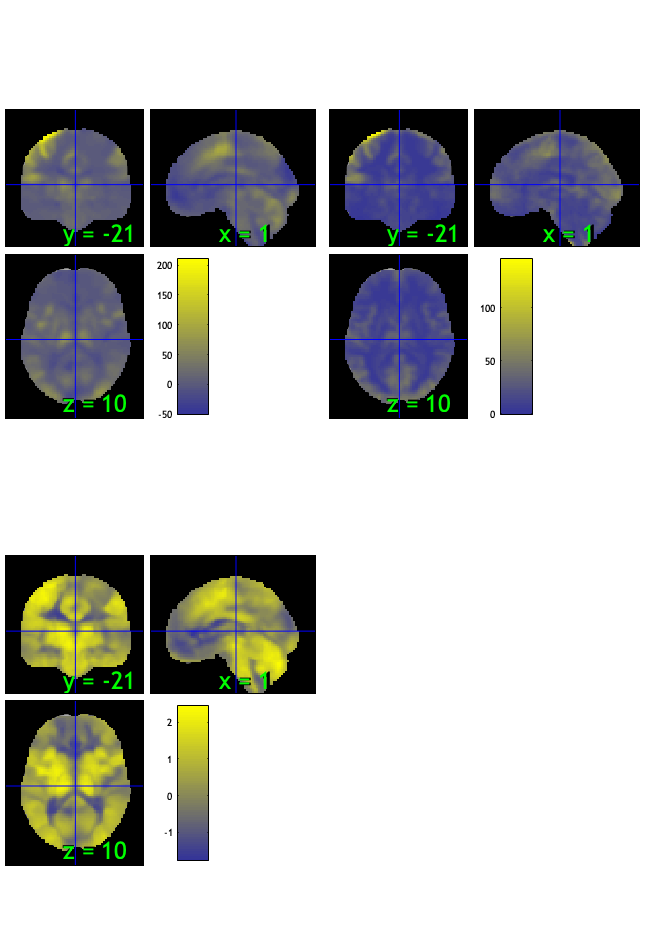

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 41.56%
Expected 3.85 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 44 
Uncorrected: 7 images		Cases 3 15 22 25 29 44 48 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 41.56%
Expected 3.85 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 5 images		Cases 2 4 22 45 71 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                             

SPM12: spm_check_registration (v7759)              11:46:00 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

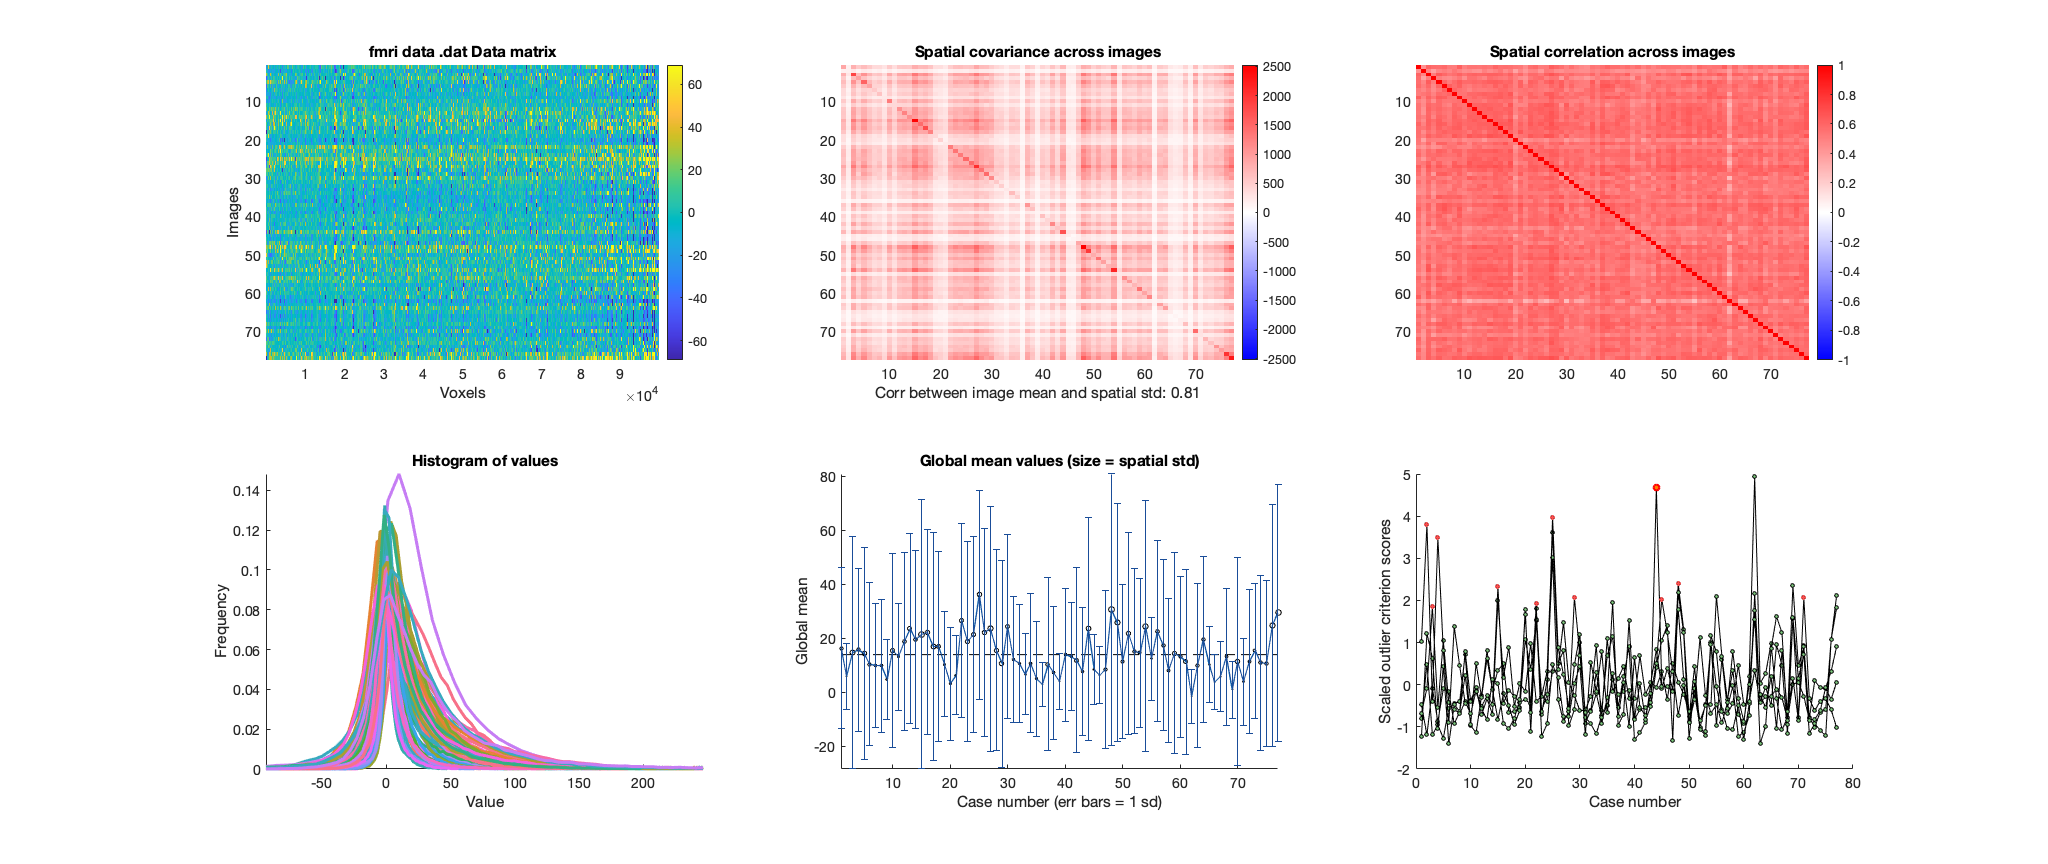

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Motor :: run robfit

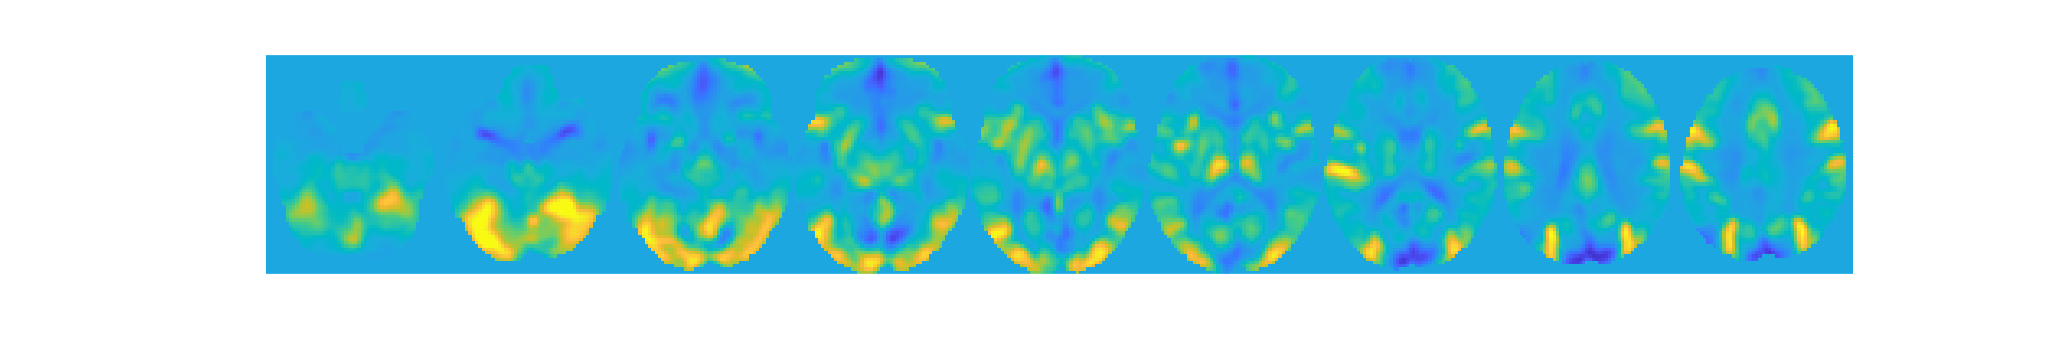

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Motor :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 77


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 1 participants, size is now 76


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

participants that are outliers:... sub-0080


disp(n);

sub-0080


#### Motor :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Motor :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


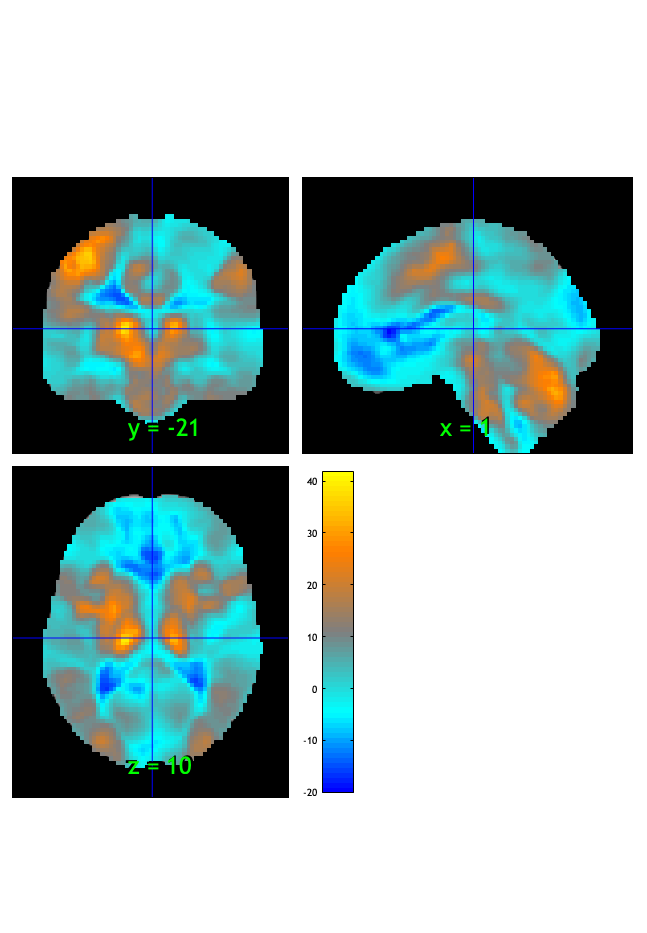

SPM12: spm_check_registration (v7759)              11:46:05 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.041217

Image   1
  5 contig. clusters, sizes   2 to 82222
Positive effect: 65633 voxels, min p-value: 0.00000000
Negative effect: 16693 voxels, min p-value: 0.00000000


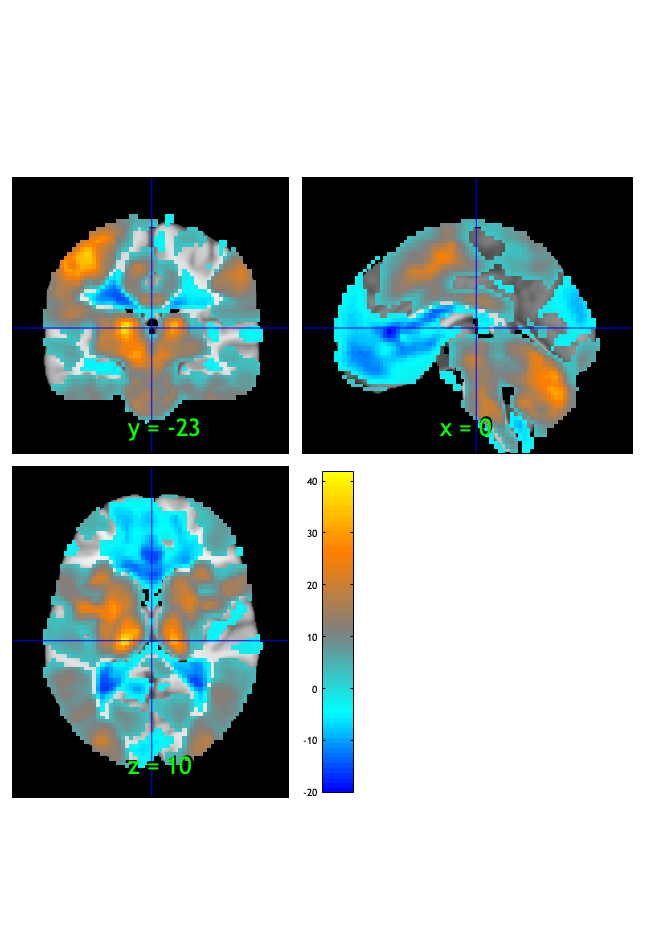

SPM12: spm_check_registration (v7759)              11:46:07 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000709

Image   1
 24 contig. clusters, sizes   1 to 70426
Positive effect: 58796 voxels, min p-value: 0.00000000
Negative effect: 11965 voxels, min p-value: 0.00000000


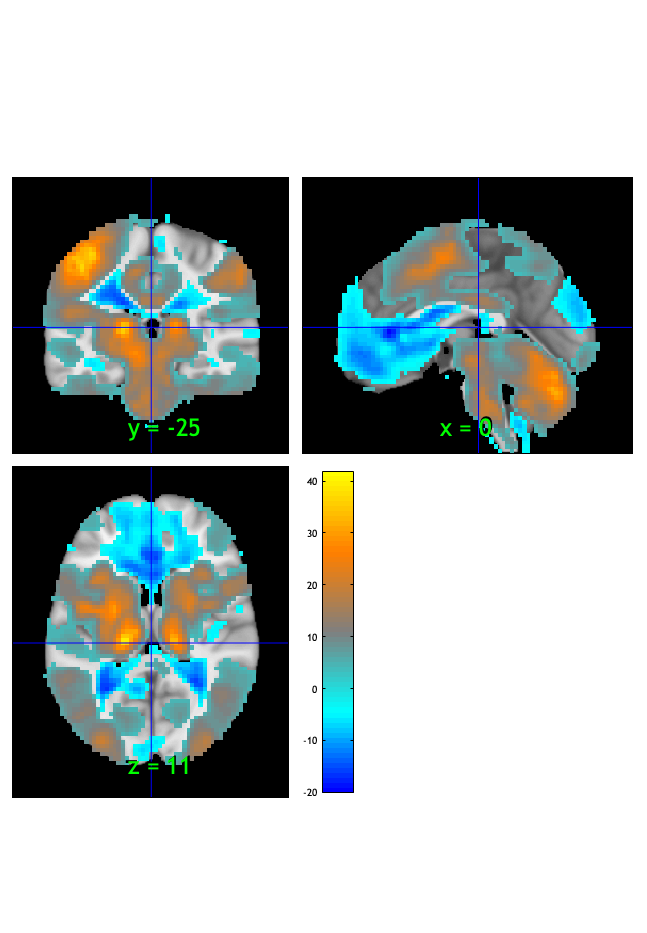

SPM12: spm_check_registration (v7759)              11:46:08 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


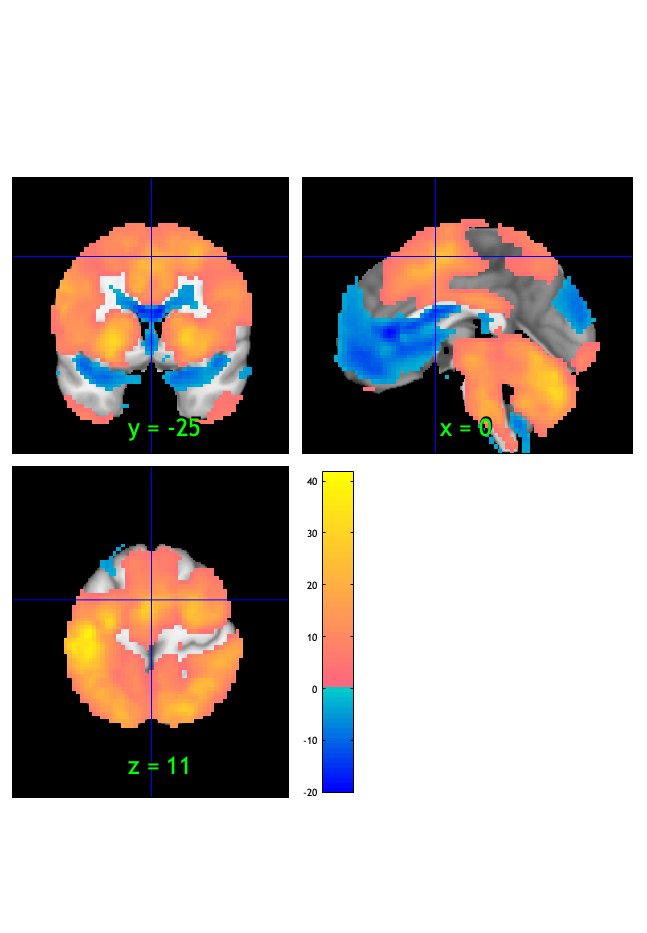

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 1728 voxels displayed, 69033 not displayed on these slices


sagittal montage: 1703 voxels displayed, 69058 not displayed on these slices


sagittal montage: 1641 voxels displayed, 69120 not displayed on these slices


axial montage: 12931 voxels displayed, 57830 not displayed on these slices


axial montage: 14185 voxels displayed, 56576 not displayed on these slices


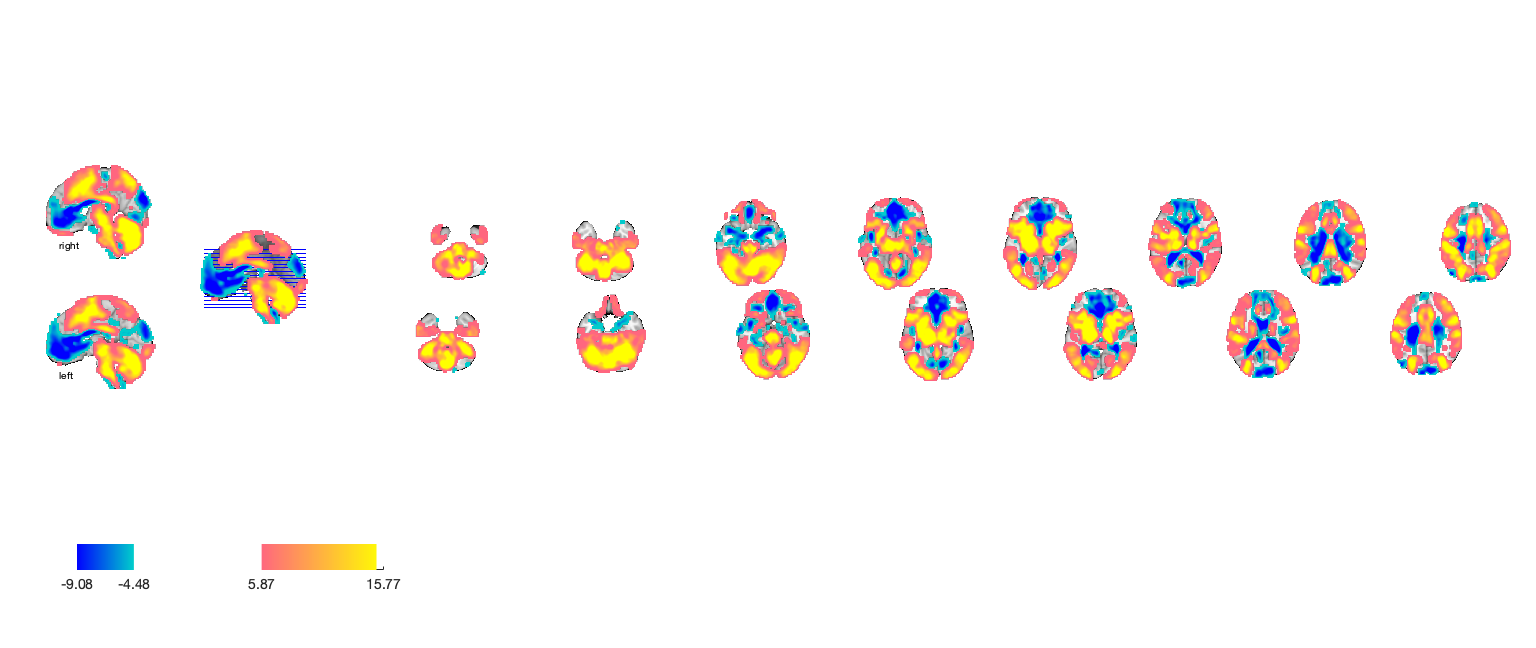

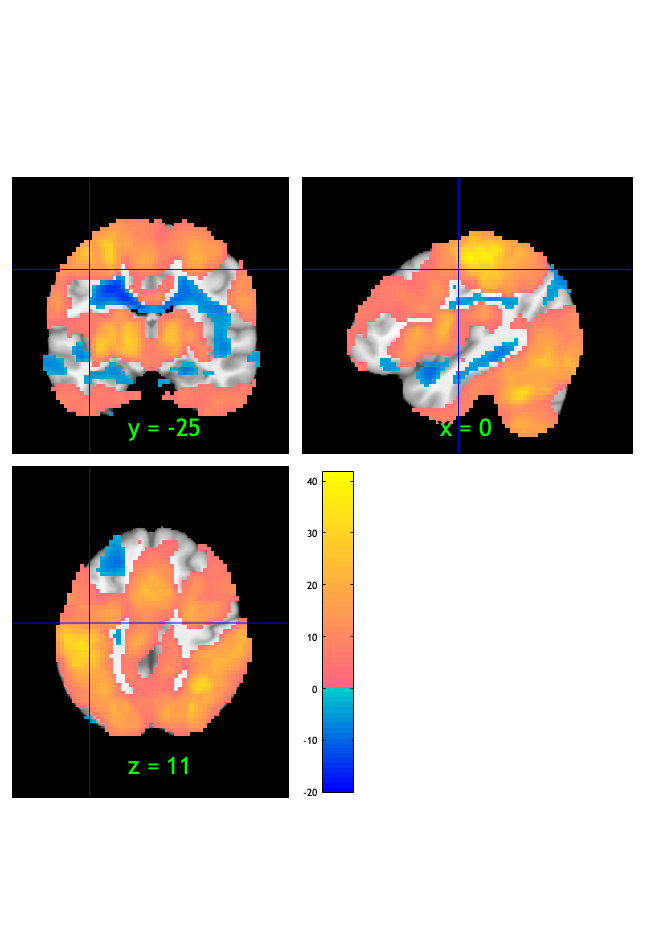

drawnow, snapnow;

#### Motor :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high   
    _________    ______________    __________    ________________

    -0.34088     {'trait'     }     0.39804      {'movements'   }
    -0.33191     {'positive'  }     0.36816      {'execution'   }
    -0.33155     {'negative'  }     0.36759      {'hand'        }
    -0.31336     {'age'       }     0.34151      {'motor'       }
    -0.30461     {'personal'  }     0.33184      {'visual'      }
    -0.29875     {'depression'}     0.32472      {'finger'      }
    -0.29603     {'emotion'   }     0.29715      {'sensorimotor'}
    -0.29382     {'person'    }     0.29287      {'action'      }
    -0.29258     {'affect'    }     0.29162      {'hands'       }
    -0.29176     {'disorder'  }   

**Motor :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(imgs2, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0151	-3.6034	0.0006	1.0000	
Cog Wholebrain	0.0310	11.0811	0.0000	1.0000	
Emo Wholebrain	-0.0134	-3.3123	0.0014	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.015066     0.0041812    -3.6032    0.00056271    -0.41331
    {'Cog Wholebrain' }     0.030997     0.0027953     11.089    2.2204e-15       1.272
    {'Emo Wholebrain' }    -0.013448     0.0040589    -3.3132     0.0014216    -0.38005



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {76×3 cell}
        text_han: {76×3 cell}
       point_han: {76×3 cell}
    star_handles: [12.0011 13.0011 14.0011]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(imgs2, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.011689     0.0038047    -3.0722     0.0029604    -0.35241
    {'Cog Wholebrain' }     0.028658     0.0025574     11.206    2.2204e-15      1.2854
    {'Emo Wholebrain' }    -0.015167     0.0037468    -4.0481    0.00012443    -0.46435



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {76×3 cell}
        text_han: {76×3 cell}
       point_han: {76×3 cell}
    star_handles: [24.0007 25.0007 26.0006]


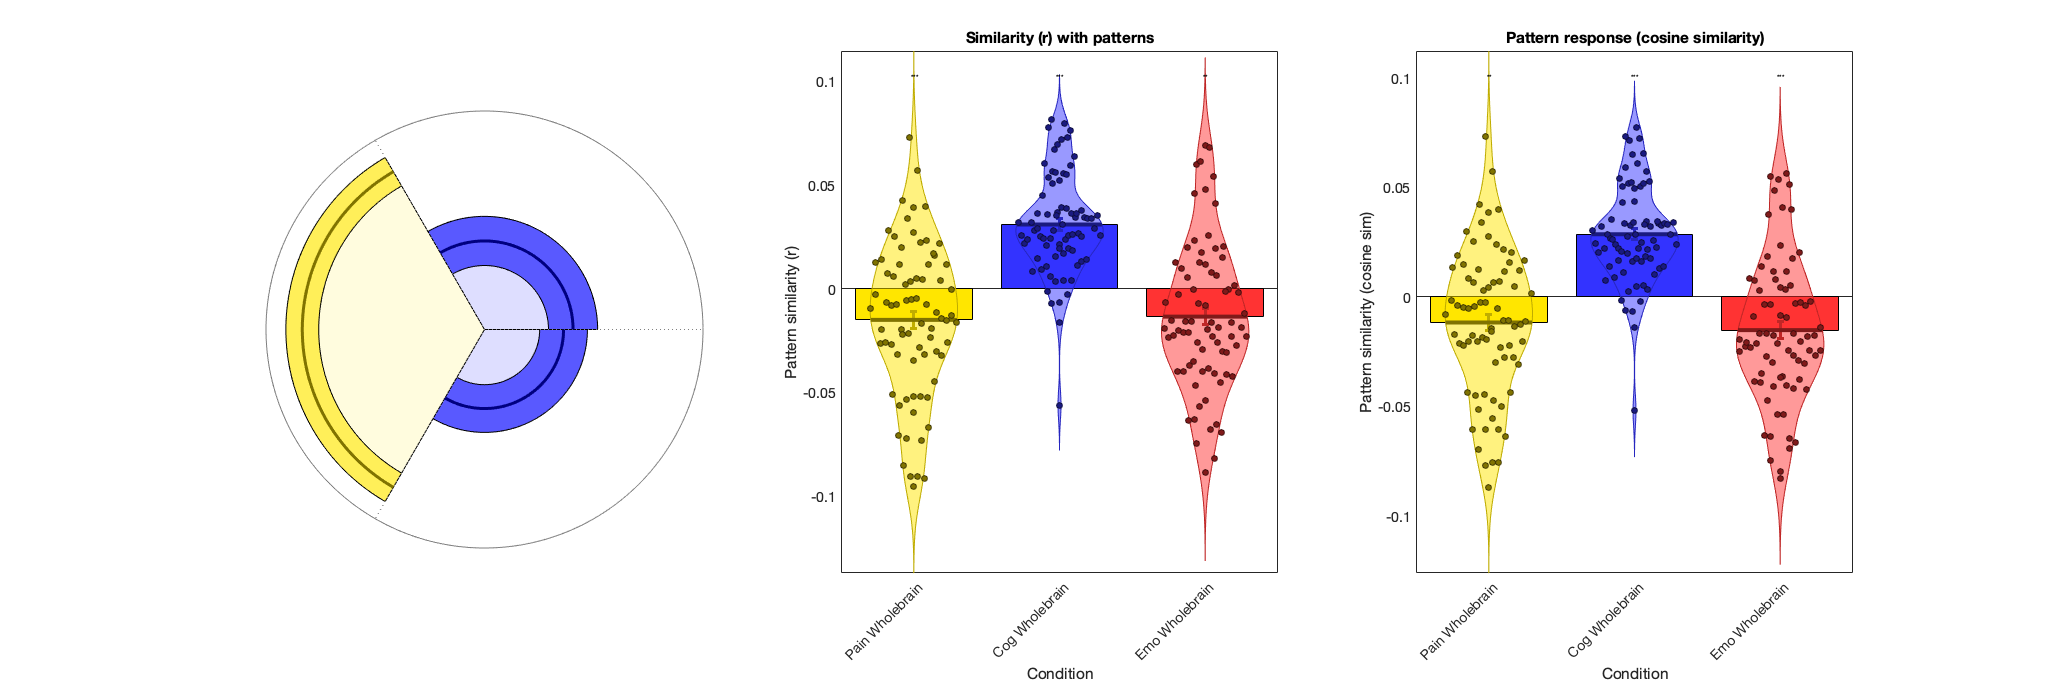

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

% save html
pubdir = pwd;
pubfilename = 's03_PVC_motor_dummy_ROI.mlx';

p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
  'format', 'html', 'outputDir', pubdir, ...
  'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
htmlfile = publish(pubfilename, p);